# RLE SSSHA Assessment

% dt_file = './data/model-RLE01_1.parquet';
% dt_file = './data/model-noDCMC-noM1C_1.parquet';
% dt_file = './data/model-DCMC-noM1C_1.parquet';
% dt_file = './data/model-DCMC-M1C_1.parquet';
% dt_file = './data/model-noDCMC-M1CwoSP_1.parquet';
% dt_file = './data/model-DCMC-M1CwoSP_1.parquet'
% dt_file = './data/model-noDCMC-M1C-DSLwoSP_1.parquet'
% dt_file = './data/model-DCMC-justFEM.parquet'
% dt_file = './data/model-noDCMC-justFEM.parquet'
% dt_file = './data/model-data_Cmnt_ssshaDEBUG_1.parquet'
% dt_file = './data/model-data_STEPmnt_WOssshaDEBUG_1.parquet'
% dt_file = './data/model-data_STEPmnt_ssshaDEBUG_1.parquet'
dt_file = './data/model-data_1.parquet'

dt_file = './data/model-data_1.parquet'

% dt_file = './data/model-RLE02dcmc_1.parquet'
% Ts = diff(t(1:2));

try
    sssha_data = parquetread(dt_file,"SampleRate",1e3,...
        "SelectedVariableNames",{'OSS00GroundAcc','OSSHardpointD','MountEncoders'}); %'OSSPayloads6D'
catch
    warning('Unable to run parquetread(). Try Matlab 2022b, or later.');
end

t = seconds(sssha_data.Time);
HP_D = reshape(cell2mat(sssha_data.OSSHardpointD),84,[]);
gnd_acc = reshape(cell2mat(sssha_data.OSS00GroundAcc),3,[]);
mnt_enc = reshape(cell2mat(sssha_data.MountEncoders),14,[]);

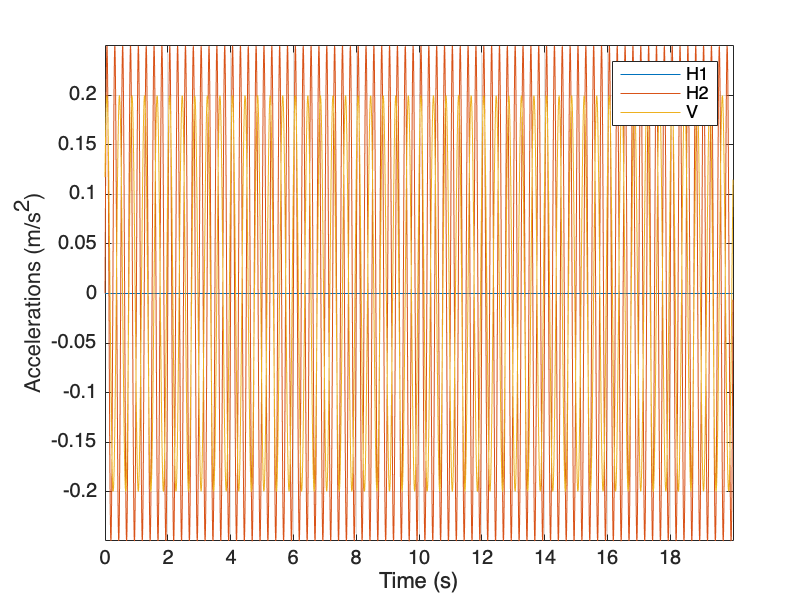

t_range = [];%[18.23,18.238];%[4.19,4.208];%[];%
if(isempty(t_range))
    t_idx  = [1, length(t)];
else
    t_idx = [find(t >= t_range(1),1,"first"),find(t < t_range(2),1,"last")];
end

if true
    plot(t(t_idx(1):t_idx(2)),gnd_acc(:, t_idx(1):t_idx(2))');
    ylabel('Accelerations (m/s^2)');
    xlabel('Time (s)');
    legend('H1','H2','V');
    grid on; axis tight;
end

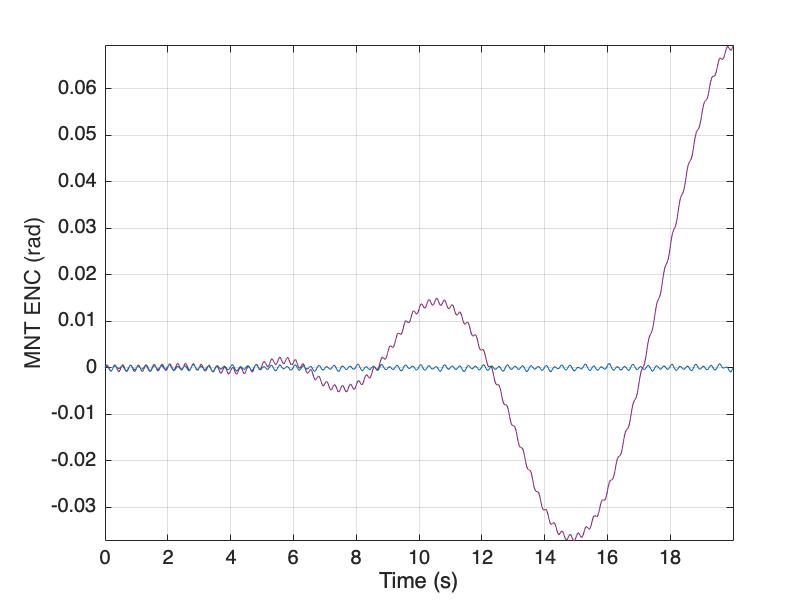


if(exist('mnt_enc','var'))
    figure
    az_enc = mnt_enc(1:4,t_idx(1):t_idx(2))';
    el_enc = mnt_enc(5:10,t_idx(1):t_idx(2))';
    gir_enc = mnt_enc(11:14, t_idx(1):t_idx(2))';
    plot(t(t_idx(1):t_idx(2)),[az_enc, gir_enc]);%,mean(mnt_enc(11:14,:))' ,mean(mnt_enc(7:10,:))'
    ylabel('MNT ENC (rad)');
    xlabel('Time (s)');
%     legend('AZ','EL','GIR');
    grid on; axis tight;
end

Structural model data

ModelFolder = "20240408_1535_zen_30_M1_202110_FSM_202305_Mount_202305_IDOM_concreteAndFoundation_finalSI_largeMass";
FileName = "modal_state_space_model_2ndOrder.mat";
    
if(~exist('inputTable','var') || 0)
    load(fullfile(im.lfFolder,ModelFolder,FileName),'inputTable','outputTable');
%     load(fullfile(im.lfFolder,ModelFolder,FileName),'inputs2ModalF','modalDisp2Outputs',...
%         'eigenfrequencies','proportionalDampingVec','inputTable','outputTable');

    fprintf('Model %s loaded from\n%s\n', FileName, ModelFolder);
    % Static solution gain matrix
    staticSolFile = fullfile(im.lfFolder,ModelFolder,"static_reduction_model.mat");
    try
        load(staticSolFile,'gainMatrixMountControlled');
        gainMatrix = gainMatrixMountControlled;
    catch
        load(staticSolFile,'gainMatrix');
    end

    fprintf('Static gain matrix loaded from\n%s\n', staticSolFile);
else
    fprintf('Using pre-loaded files\n');
end

Using pre-loaded files


HP axial forces

i_in = inputTable{"OSS_Harpoint_delta_F","indices"}{1};
i_out = outputTable{"OSS_Hardpoint_D","indices"}{1};
T_hp = kron(eye(7),[-eye(6),eye(6)]);

HPk = 1./ diag(T_hp*gainMatrix(i_out,i_in));
fprintf('HP stiffness: (avg) %g (N/um), std:%g', mean(1e-6*HPk), std(1e-6*HPk))

HP stiffness: (avg) 144.144 (N/um), std:0.0581975

% invOM2 = diag(1./((2*pi*eigenfrequencies).^2));
% HPk_modal = 1./diag(T_hp * modalDisp2Outputs(i_out,:) * invOM2 * inputs2ModalF(:,i_in));
% fprintf('HP stiffness (from modal model): (avg) %g (N/um), std:%g', mean(1e-6*HPk_modal), std(1e-6*HPk_modal))

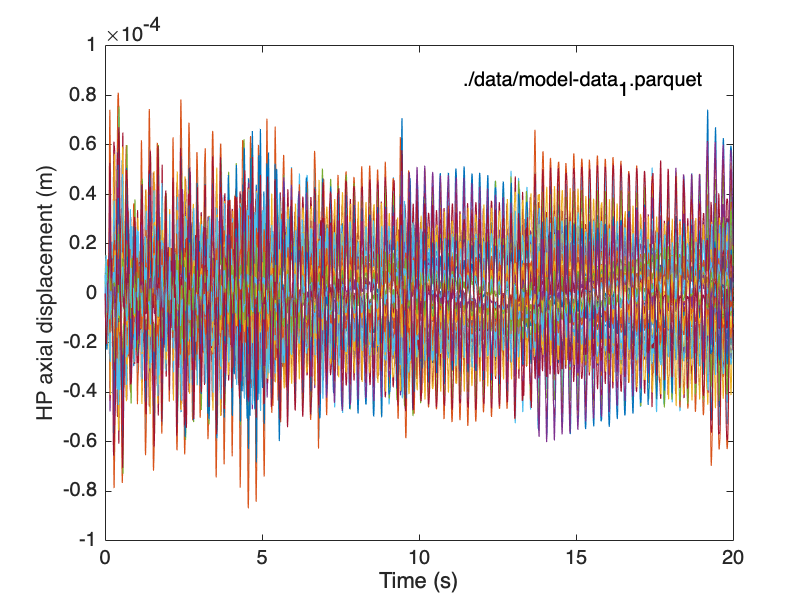

HP_axialF = T_hp * HP_D;%mean(HPk) * 

t_range = [];%[];%[4.19,4.203];%
if(isempty(t_range))
    t_idx  = [1, length(t)];
else
    t_idx = [find(t >= t_range(1),1,"first"),find(t < t_range(2),1,"last")];
end
figure
plot(t(t_idx(1):t_idx(2)), HP_axialF(:,t_idx(1):t_idx(2))');
ylabel('HP axial displacement (m)'); % ylabel('HP Forces (N)');
xlabel('Time (s)');
% grid on; axis tight;
NE = [max(xlim) max(ylim)]-[diff(xlim) diff(ylim)]*0.05;
text(NE(1), NE(2), dt_file,'VerticalAlignment','top', 'HorizontalAlignment','right')

HP stiffness due to mode truncation

if false
    freq_lim_vec = (45:1:max(eigenfrequencies))'; %#ok<*UNRCH> 
    HPk_dyn = zeros(numel(freq_lim_vec),2);
    for iw = 1:numel(freq_lim_vec)
        maxf_i = find(eigenfrequencies <= freq_lim_vec(iw),1,"last");
        invOM2_ = diag(1./((2*pi*eigenfrequencies(1:maxf_i)).^2));
        HPk_ = 1./diag(T_hp * modalDisp2Outputs(i_out,1:maxf_i) * invOM2_ * inputs2ModalF(1:maxf_i,i_in));
        HPk_dyn(iw,:) = [mean(HPk_), std(HPk_)];
    end
    figure
    plot(freq_lim_vec,HPk_dyn(:,1),'s:');
    hold on; semilogy(max(eigenfrequencies),mean(HPk_modal),'x');
    grid on;
    xlabel('Max mode frequency (Hz)');
    ylabel('HP stiffness (N/m)')
end